# 8장 예제

## 8-1

clc; clear; close all
s = tf('s');
sys1 = 1/((s+2)*(s+4)*(s+10));
figure(1)
subplot(1,2,1)
rlocus_perf_lines(sys1, 0, "overshoot", 0.0948)

overshoot 9.48% 를 만족하는 theta=36.87 deg


zeta 0.60% 를 만족하는 theta=36.87 deg


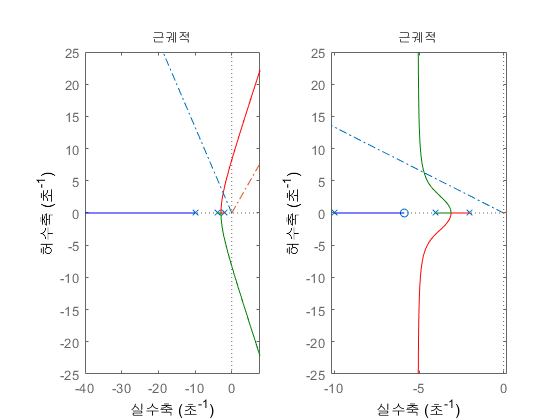

overshoot 9.48% 를 만족하는 theta=36.87 deg


zeta 0.60% 를 만족하는 theta=36.87 deg


sys2 = 55.39*(s+5.868)/((s+2)*(s+4)*(s+10));
subplot(1,2,2)
rlocus_perf_lines(sys2, 0, "overshoot", 0.0948)

## 8-2

clc; clear; close all
s = tf('s');
sys1 = 1/(s*(s+4)*(s+10));
figure(1)
subplot(1,2,1)
rlocus_perf_lines(sys1, 0, "overshoot", 0.2)

overshoot 20.00% 를 만족하는 theta=27.13 deg


zeta 0.46% 를 만족하는 theta=27.13 deg


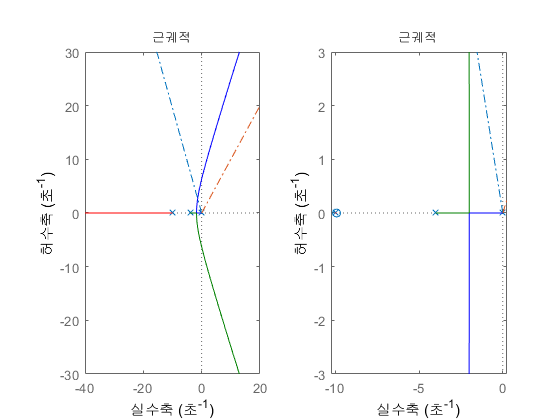

overshoot 20.00% 를 만족하는 theta=27.13 deg


zeta 0.46% 를 만족하는 theta=27.13 deg


sys2 = 19.61*(s+9.917)/(s*(s+4)*(s+10));
subplot(1,2,2)
rlocus_perf_lines(sys2, 0, "overshoot", 0.2)

## 8-3

clc; clear; close all
s = tf('s');
sys1 = 242/((s+3)*(s+5)*(s+10));
sys2 = 123*(s+7)/((s+3)*(s+5)*(s+10));
sys3 = 120*(s+0.1)*(s+7)/(s*(s+3)*(s+5)*(s+10));

figure(1)
t = 0:0.01:30;
step_feedback(sys1, t)


sys =
 
             242
  -------------------------
  s^3 + 18 s^2 + 95 s + 392
 
Continuous-time transfer function.

% overshoot: 18.11

hold on
step_feedback(sys2, t)


sys =
 
          123 s + 861
  ---------------------------
  s^3 + 18 s^2 + 218 s + 1011
 
Continuous-time transfer function.

% overshoot: 21.18

step_feedback(sys3, t)


sys =
 
          120 s^2 + 852 s + 84
  ------------------------------------
  s^4 + 18 s^3 + 215 s^2 + 1002 s + 84
 
Continuous-time transfer function.

% overshoot: 3.59

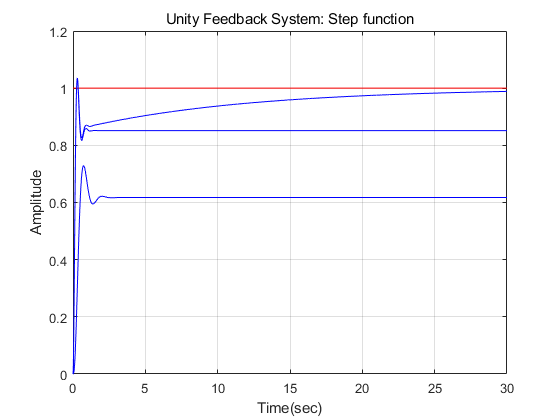

hold off
xlabel('Time(sec)')
ylabel('Amplitude')
title('Unity Feedback System: Step function')
grid

function step_feedback(open_loop, t)
    sys = feedback(open_loop, 1)
    [y,t]=step(sys, t);
    [num, den] = tfdata(sys, 'v');
    final_value = num(end) / den(end);
    y_max = max(y);
    ovshoot = (y_max-final_value)/final_value * 100;
    fprintf('%% overshoot: %1.2f%', ovshoot)
    u=ones(size(t));
    plot(t,u,'r-', t,y,'b-')
end

